# Lab 4

clear;
warning("off");

## Experiment 1

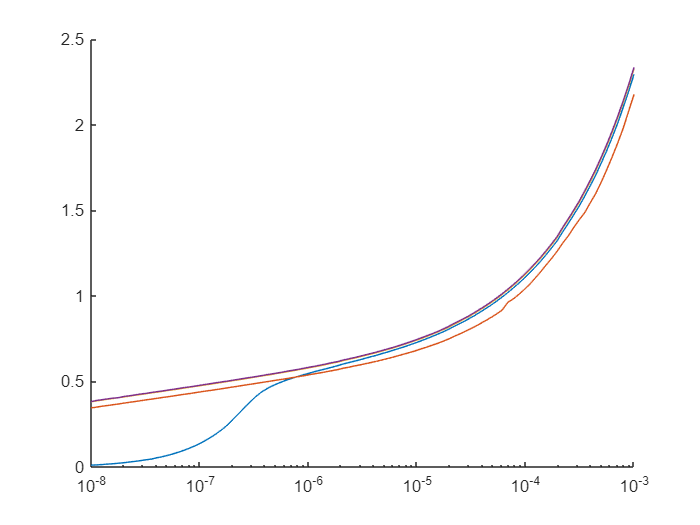

load("Ex_1_1.mat")

voltage1 = Diode_Voltage;
current1 = ch1;

load("Ex_1_2.mat")
voltage2 = Diode_Voltage;
current2 = ch1;

load("Ex_1_3.mat")

voltage3 = Diode_Voltage;
current3 = ch1;

load("Ex_1_4.mat")

voltage4 = Diode_Voltage;
current4 = ch1;
figure(1)
hold on 
plot(current1,voltage1)
plot(current2,voltage2)
plot(current3,voltage3)
plot(current4,voltage4)
set(gca, "XScale", "log");
hold off

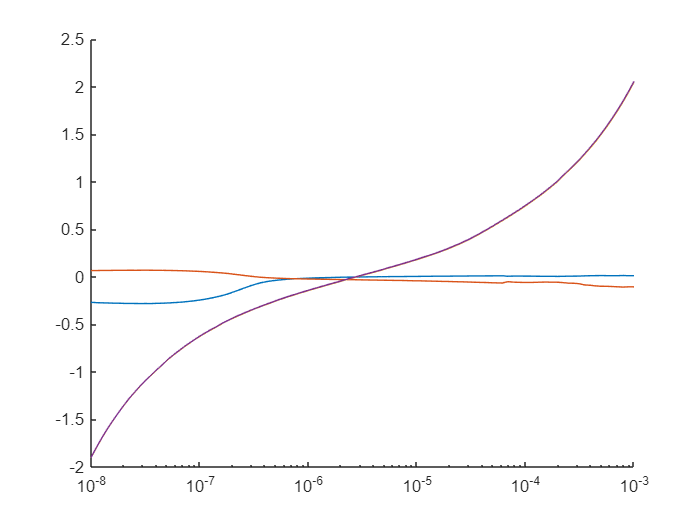

mean = (voltage1 + voltage2 + flip(voltage3) + flip(voltage4))/4;

clf;
figure(2)
hold on

plot(current1, voltage1 - mean)
plot(current2, voltage2 - mean)
plot(current3, voltage3 - mean)
plot(current4, voltage4 - mean)
set(gca, "XScale", "log");
hold off

## Experiment 2

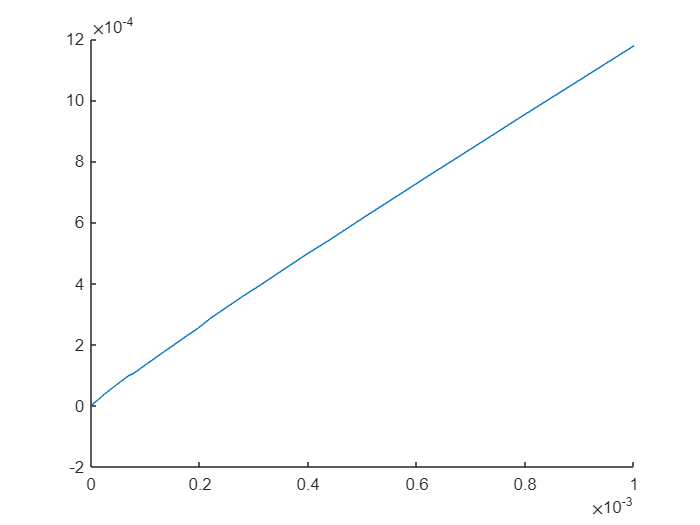

clear;
clf;
load("Ex_2_1.mat");
figure(3);
hold on
loglog(ch1, MDiode_Current);
hold off

## Experiment 3

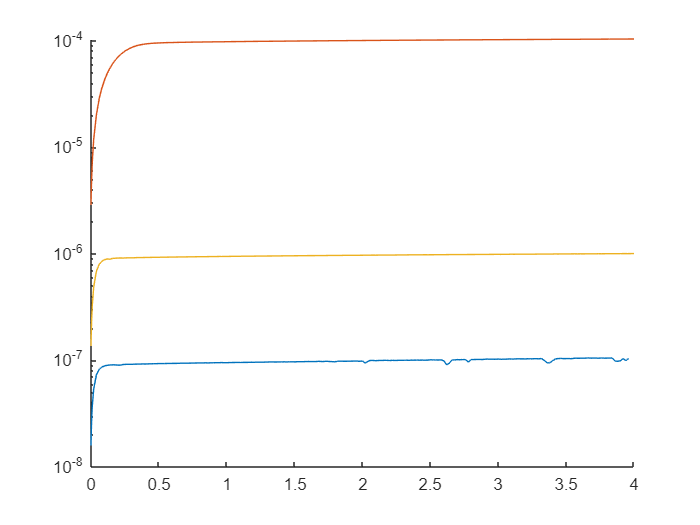

clear;
clf;
load("Ex_3_100nano.mat");
nano_100_voltage = ch2_voltage;
nano_100_current = mos_current;
load("Ex_3_1micro.mat");
micro_1_voltage = ch2_voltage;
micro_1_current = mos_current;
load("Ex_3_100micro.mat")
micro_100_voltage = ch2_voltage;
micro_100_current = mos_current;

figure();
hold on
plot(nano_100_voltage, nano_100_current);
plot(micro_100_voltage, micro_100_current);
plot(micro_1_voltage, micro_1_current);
set(gca, "YScale", "log");
xlim([0 4])
hold off